**CEL ĆWICZENIA**

W ramach tego ćwiczenia zostanie opracowany bardziej zaawansowany model matematyczny dla systemu zawieszenia samochodu skupiającego się na jednym kole. Celem jest wykonanie symulacji, które pozwolą na uzyskanie odpowiedzi skokowej oraz reakcji układu na serię wymuszeń, symulując realistyczne warunki drogowe. Na podstawie przeprowadzonych obliczeń model zostanie zaimplementowany w środowisku SIMULINK, wykorzystując dwa różne podejścia.

Na samym początku zbudowałem zmienne stanów. Zgodnie z poleceniem zdefiniowałem parametry, gdzie :

 m1 – masa koła z wahaczem ,

 m2 – masa ćwiartki nadwozia ,

 k1 – współczynniki sprężystości opony, 

k2 – współczynniki sprężystości sprężyny,

 b1 – współczynnik tłumienia opony,

 b2 – współczynnik tłumienia amortyzatora olejowego,

 y1 – pionowe przesunięcie środka masy opony,

 y2 – pionowe przesunięcie środka masy nadwozia 

Dalej musiałem przypisać odpowiednie komórki do macierzy A B C oraz D. Całość włożyłem do funkcji ss gdzie odbyło się przekształcenie na 4 różne wykresy. Całość sprawdziłem odpowiedzią na skok funkcją step z ustawieniem odpowiedniego czasu. 

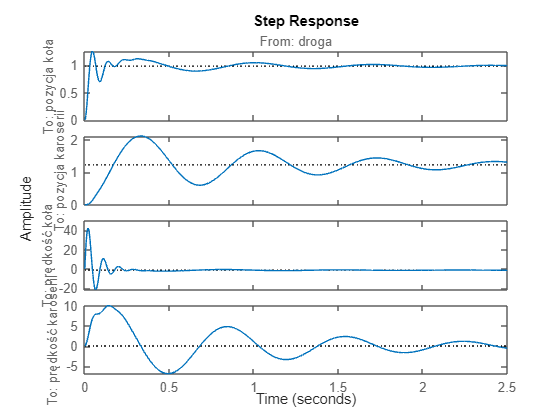

m1 = 50;     %kg
m2 = 370;    %kg
k1 = 220000; %N/m
k2 = 35000;  %N/m
b1 = 500;    %Ns/m
b2 = 1000;   %Ns/m
A = [0 0 1 0; 0 0 0 1 ; -(k1 + k2) / m1 k2/m1 -(b1 + b2) / m1 b2/m1 ; k2/m2 -k2/m2 b2/m2 -b2/m2];
B = [b1/m2; 0; k1/m1 - ((b1+b2) * b1) / (m1 * m1); b1 * b2 / (m1 * m2)];
C = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
D = [0; 0;0;0];
sys = ss(A,B,C,D,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'});
step(sys,0:0.001:2.5 )

W ćwiczeniu szczególną rolę odgrywa możliwość opisywania zarówno sygnałów wejściowych, jak i wszystkich zmiennych stanu oraz zmiennych wyjściowych, które są definiowane właśnie jako zmienne stanu. Taki sposób opisu umożliwia dokładniejsze śledzenie zachowania całego modelu.

Zauważamy, że układ działa zgodnie z założeniami: koło reaguje na gwałtowny skok podłoża szybkimi, tłumionymi oscylacjami, natomiast karoseria przemieszcza się wolniej i bardziej płynnie, nie oddalając się znacząco od równowagi. To korzystnie wpływa na komfort pasażerów, ponieważ odczucie nierówności drogi jest zminimalizowane. Na wykresie prędkości widać gwałtowny wzrost i silne tłumienie dla koła, podczas gdy zmiana prędkości kabiny jest łagodniejsza i ma mniejszą amplitudę. 

Następne zadanie polegało na delikatnej modyfikacji kodu. W nowej macierzy `C1` definiuję tylko dwie zmienne wyjściowe: pozycję koła i pozycję karoserii, co pozwala mi skupić się na ich przemieszczeniach. Dla tej zmienionej konfiguracji wyjść wyeliminowałem prędkości z wynikowych sygnałów wyjściowych. Zmiana ta miała wpływ na wykres: początkowo pełny model zawierał zarówno pozycje, jak i prędkości, co pozwalało obserwować szczegółowe tłumienie drgań w obu zmiennych. Teraz wykres przedstawia wyłącznie reakcję pozycji koła i karoserii na wymuszenie, eliminując informacje o prędkościach. Dzięki temu wizualizacja jest bardziej przejrzysta i pozwala na łatwiejsze zrozumienie samego przemieszczenia obu elementów układu, co ułatwia analizę ich dynamiki w reakcji na skok jednostkowy

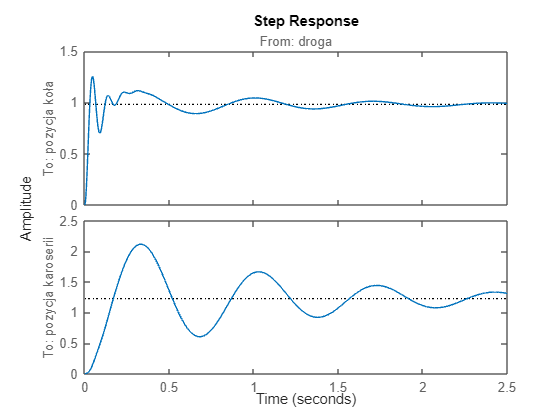

C1 = [1 0 0 0; 0 1 0 0];
D1 = [0;0];
sys = ss(A,B,C1,D1,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName',{'pozycja koła', 'pozycja karoserii'});
step(sys,0:0.001:2.5);

Ostatnie polecenie dotyczące tematu wyświetlania wykresów w różnych konfiguracjach polegało na zmodyfikowaniu kodu tak, aby wyjściami były tylko prędkości koła i karoserii. W tym celu zdefiniowałem nową macierz C

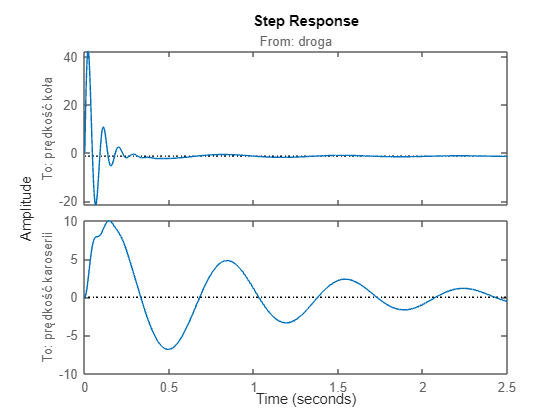

C2 = [0 0 1 0; 0 0 0 1];
D2 = [0;0];
sys = ss(A,B,C2,D2,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName',{'prędkość koła', 'prędkość karoserii'});
step(sys,0:0.001:2.5);

W tym kodzie generuję sygnał, który posłuży jako wymuszenie dla układu. Na początku tworzę wektor czasu t z krokiem co 0,001 sekundy i zakresem do 9 sekund, aby zapewnić odpowiednią dokładność analizy czasowej. Następnie definiuję okres sygnału T, odpowiadający jednemu pełnemu cyklowi.Używam funkcji mod(nie byłem w stanie użyć w tym celu funkcji square gdyż po wielu próbach nie byłem w stanie zaistalować toolboxa Signal Processing Toolbox) do generacji sygnału prostokątnego: wyrażenie mod(t, T) < T / 2 sprawdza, czy bieżący czas mieści się w pierwszej połowie okresu, co tworzy sygnał, który przyjmuje wartości dodatnie przez połowę okresu i wartości ujemne przez drugą połowę. Następnie mnożę wynik przez 0,1, aby ustawić amplitudę sygnału na poziomie 0,1, uzyskując finalny przebieg wymuszenia u.Na końcu stosuję funkcję lsim, aby zasymulować reakcję układu sys na to wymuszenie prostokątne u w zadanym czasie t.

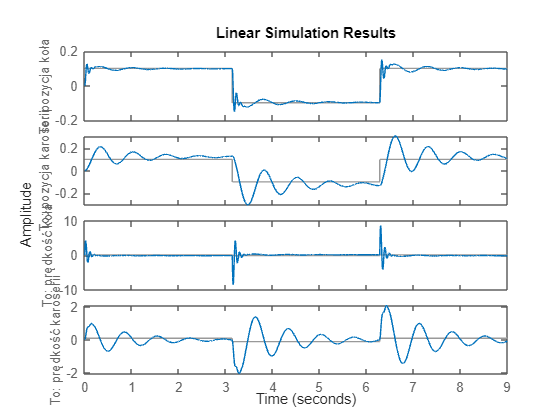

t = 0:0.001:9;
T = 2 * pi;
u = 0.1 * (mod(t, T) < T / 2) * 2 - 0.1;
sys = ss(A,B,C,D,...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'},...
    'OutputName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'});
lsim(sys,u, t);

Układ zachowuję się prawidłowo zarówno przy wieżdżaniu jak i zjeżdżaniu auta z krawężnika.

Kolejne zadanie polegało na wyznaczeniu transmitancji układu. Najpierw używam funkcji ss2tf, która przekształca macierze stanu A, B, C, D na postać transmitancyjną. Wynikiem tej operacji są macierze licz i mian, reprezentujące licznik i mianownik transmitancji dla każdego wyjścia systemu. Następnie tworzę cztery różne transmitancje: G1, G2, G3 i G4. Każda z nich odpowiada innemu wyjściu systemu i wykorzystuje odpowiedni wiersz macierzy licz. Przypisuję te transmitancje do tego samego sygnału wejściowego, czyli droga, oraz tej samej zmiennej wyjściowej, czyli pozycja koła. Na końcu wywołuję funkcję step, aby wygenerować odpowiedzi skokowe dla wszystkich czterech transmitancji w zakresie od 0 do 2,5 sekundy.

[licz,mian] = ss2tf(A,B,C,D);
G1 = tf(licz(1,:),mian,'InputName','droga','OutputName','pozycja koła')

G1 =
 
  From input "droga" to output "pozycja koła":
     1.351 s^3 + 4144 s^2 + 1.179e04 s + 4.08e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G2 = tf(licz(2,:),mian,'InputName','droga','OutputName','pozycja koła')

G2 =
 
  From input "droga" to output "pozycja koła":
          27.03 s^2 + 1.202e04 s + 5.109e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G3 = tf(licz(3,:),mian,'InputName','droga','OutputName','pozycja koła')

G3 =
 
  From input "droga" to output "pozycja koła":
     4100 s^3 + 4730 s^2 + 3.907e05 s - 5.625e05
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


G4 = tf(licz(4,:),mian,'InputName','droga','OutputName','pozycja koła')

G4 =
 
  From input "droga" to output "pozycja koła":
  27.03 s^3 + 1.202e04 s^2 + 5.109e05 s + 5.45e-09
  -------------------------------------------------
  s^4 + 32.7 s^3 + 5222 s^2 + 1.284e04 s + 4.162e05
 
Continuous-time transfer function.
Model Properties


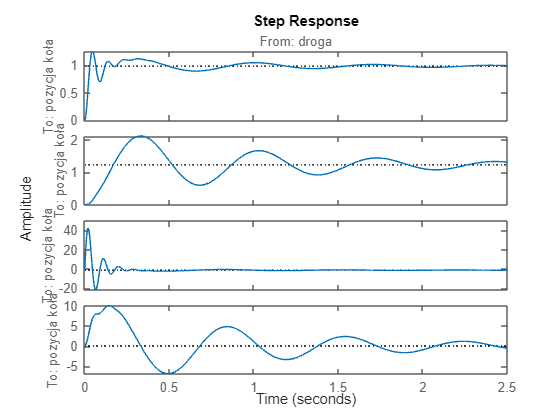

step([G1; G2; G3; G4], 0:0.001:2.5)

Wyrysowane wykresy są takie same jak w poprzednim przykładzie co oznacza, że przytoczona metoda jest również poprawna.